# 🌡️ Exercise #1: matTFA tutorial

Note: This tutorial is directly borrowed from the matTFA repo, with some minor modifications (see [script](https://github.com/EPFL-LCSB/matTFA/blob/master/tutorials/tutorial.m)).

The goal is to learn the basics of running thermodynamic-based flux analysis (TFA), including key functions used, as well as required input files & data.

## Loading the input files

- Small* E. coli* model

- Thermodynamic properties DB

% make sure solver is set
changeCobraSolver('cplex_direct')

ans = logical
   1



%% load the model
load('smallEcoli.mat');
mymodel = smallEcoli;

% Limit the bounds of the fluxes that are higher than 100 or lower than
% -100 mmol/(gDW * h)
if any(mymodel.lb<-100) || any(mymodel.ub>100)
    mymodel.lb(mymodel.lb<-100) = -100;
    mymodel.ub(mymodel.ub>+100) = +100;
end

%% Load the thermodynamics database
tmp = load('../Exercise_2/thermo_data.mat');
ReactionDB = tmp.DB_AlbertyUpdate;
clear tmp

## FBA, FVA, and blocked reactions

- Run FBA simulation with the `optimizeCbModel()` function

- Run FVA with the `runMinaMax()` function

- Remove blocked reactions with the `removeRxns()` function

% Test simple fba
solFBA = optimizeCbModel(mymodel);

% We can set a lower bound for growth (e.g. 50% of maximal growth)
min_obj = roundsd(0.5*solFBA.f, 2, 'floor');
mymodel.lb(mymodel.c==1) = min_obj;

%% Perform FVA 
fva = runMinMax(mymodel);

minmax for DM_4CRSOL	min: 1.159600e-04	 max: 2.344191e-04
minmax for DM_5DRIB	min: 1.201200e-04	 max: 2.428287e-04
minmax for DM_AMOB	min: 1.040000e-06	 max: 1.884814e-06
minmax for DM_MTHTHF	min: 6.968000e-04	 max: 1.408617e-03
minmax for Ec_biomass_iJO1366_WT_53p95M	min: 5.200000e-01	 max: 1.051207e+00
minmax for DM_5mtr_e	min: 3.506880e-03	 max: 1.289499e+00
minmax for DM_ac_e	min: 1.082895e-01	 max: 3.717188e-01
minmax for DM_acald_e	min: 0	 max: 5.775503e-03
minmax for DM_ala-D_e	min: 1.262664e-02	 max: 2.552540e-02
minmax for DM_ala-L_e	min: 0	 max: 8.246992e+00
minmax for DM_alaala_e	min: 3.146000e-04	 max: 6.359800e-04
minmax for DM_arg-L_e	min: 0	 max: 4.123496e+00
minmax for DM_asn-L_e	min: 0	 max: 8.246992e+00
minmax for DM_asp-L_e	min: 0	 max: 8.246992e+00
minmax for DM_ca2_e	min: -5.205575e-03	 max: -2.575040e-03
minmax for DM_cbl1_e	min: -2.344191e-04	 max: -1.159600e-04
minmax for DM_cl_e	min: -5.205575e-03	 max: -2.575040e-03
minmax for DM_co2_e	min: -5.746481e+00	 max:


% Are there any blocked reactions?
% solver tolerance is 1e-9
SolTol = 1e-9;
id_Blocked_in_FBA = find( (fva(:,1)>-SolTol & fva(:,1)<SolTol) & ...
                          (fva(:,2)>-SolTol & fva(:,2)<SolTol) );

% If there exist block reactions
while ~isempty(id_Blocked_in_FBA)
    % remove them
    mymodel = removeRxns(mymodel, mymodel.rxns(id_Blocked_in_FBA));
    fva = runMinMax(mymodel);
    id_Blocked_in_FBA = find( (fva(:,1)>-SolTol & fva(:,1)<SolTol) & ...
                              (fva(:,2)>-SolTol & fva(:,2)<SolTol) );
end

## TFA & TFA with concentration data

- `prepModelforTFA()`: inputs model + thermo_data, calculates gibbs energies of reactions, outputs prepared model

- `convToTFA()`: inputs prepared model, adds new thermodynamic constraints based on gibbs energies, outputs converted model

- `addNetFluxVariables()`: inputs converted model, adds net flux variables and constraints to model, outputs TFA-ready model

- `solveTFAmodelCplex()`: inputs TFA-ready model, outputs TFA solution

% prepare model for TFA
if ~isfield(mymodel, 'id')
    mymodel.id = mymodel.description;
end
prepped_m = prepModelforTFA(mymodel, ReactionDB, mymodel.CompartmentData);

metCompSymbol used
Checking for transport reactions
Fetching compounds thermodynamic data
matching 1 = 10fthf_c
10fthf_c	pH: 7.500000e+00	is: 2.500000e-01	DGstd: -1.447700e+02	DGtr: -1.447700e+02
matching 2 = 13dpg_c
13dpg_c	pH: 7.500000e+00	is: 2.500000e-01	DGstd: -5.868000e+02	DGtr: -5.868000e+02
matching 3 = 2dmmql8_c
2dmmql8_c	pH: 7.500000e+00	is: 2.500000e-01	DGstd: 1.819010e+02	DGtr: 1.819010e+02
met 4: [2Fe-2S] iron-sulfur cluster not found in ReactionDB
matching 5 = 2pg_c
2pg_c	pH: 7.500000e+00	is: 2.500000e-01	DGstd: -3.719000e+02	DGtr: -3.719000e+02
matching 6 = 3pg_c
3pg_c	pH: 7.500000e+00	is: 2.500000e-01	DGstd: -3.719000e+02	DGtr: -3.719000e+02
matching 7 = 4crsol_c
4crsol_c	pH: 7.500000e+00	is: 2.500000e-01	DGstd: -1.153000e+01	DGtr: -1.153000e+01
met 8: [4Fe-4S] iron-sulfur cluster not found in ReactionDB
matching 9 = 5drib_c
5drib_c	pH: 7.500000e+00	is: 2.500000e-01	DGstd: -1.453900e+02	DGtr: -1.453900e+02
matching 10 = 5mthf_c
5mthf_c	pH: 7.500000e+00	is: 2.500000e-01	


%% Convert to TFA
tmp = convToTFA(prepped_m, ReactionDB, [], 'DGo', [], min_obj);

Converting the model into TFA and testing feasibility...
Checking for transport reactions
Generating thermodynamic constraints for metabolites
generating thermo variables for 10fthf_c
generating thermo variables for 13dpg_c
generating thermo variables for 2dmmql8_c
NOT generating thermo variables for 2fe2s_c
generating thermo variables for 2pg_c
generating thermo variables for 3pg_c
generating thermo variables for 4crsol_c
NOT generating thermo variables for 4fe4s_c
generating thermo variables for 5drib_c
generating thermo variables for 5mthf_c
generating thermo variables for accoa_c
NOT generating thermo variables for adocbl_c
generating thermo variables for adp_c
generating thermo variables for adpglc_c
generating thermo variables for ala-L_c
generating thermo variables for amet_c
generating thermo variables for amob_c
generating thermo variables for amp_c
generating thermo variables for arg-L_c
generating thermo variables for asn-L_c
generating thermo variables for asp-L_c
generatin

The slack variables that need to be non-zero, are:
DGPosSlack_PGK
DGNegSlack_GAPD
Relaxation of DGo_PGK : -6.900 +- 0.290 (sigma) ---> -6.900 +- 3*0.290 
Relaxation of DGo_GAPD : -0.356 +- 1.195 (sigma) ---> -0.356 +- 2*1.195 
It was not possible to obtain TFA-feasible solutions with the original DGo values calculated by GCM!
We had to relax the following DGo ranges as follows:


ans = 3×5 cell array
    {'varName' }    {'LB-before'}    {'UB-before'}    {'LB-relaxed'}    {'UB-relaxed'}
    {'DGo_PGK' }    {[  -7.1904]}    {[  -6.6096]}    {[   -7.7712]}    {[   -6.0288]}
    {'DGo_GAPD'}    {[  -1.5510]}    {[   0.8390]}    {[   -2.7460]}    {[    2.0340]}



% Add net flux variables, which are equal to forwards flux - backwards flux
% NF_rxn = F_rxn - B_rxn
this_tmodel = addNetFluxVariables(tmp);

%% Solve tFA
soltFA = solveTFAmodelCplex(this_tmodel);

%% Perform TVA
% Get the variables representing the net fluxes
NF_ix = getAllVar(this_tmodel,{'NF'});

tva = runTMinMax(this_tmodel, this_tmodel.varNames(NF_ix));

Maximizing NF_LMPD_GAM_c_1_31



%% We add some generic data for cofactor concentrations
metNames = {'adp_c', 'amp_c', 'atp_c'};
C_lb = [1e-06, 1e-6, 1e-03]';
C_ub = [7e-04, 1e-2, 5e-02]';
LC_varNames = {'LC_adp_c', 'LC_amp_c', 'LC_atp_c'};
% find the indices of these variables in the variable names of the tfa
id_LC_varNames = find_cell(LC_varNames, this_tmodel.varNames);
% Set to the model these log-concentration values
this_tmodel.var_lb(id_LC_varNames) = log(C_lb);
this_tmodel.var_ub(id_LC_varNames) = log(C_ub);

% Run another tva with the data
tva_wData = runTMinMax(this_tmodel, this_tmodel.varNames(NF_ix));

Maximizing NF_LMPD_GAM_c_1_31


## Visualize bidirectional reactions that become unidirectional with thermodynamic constraints

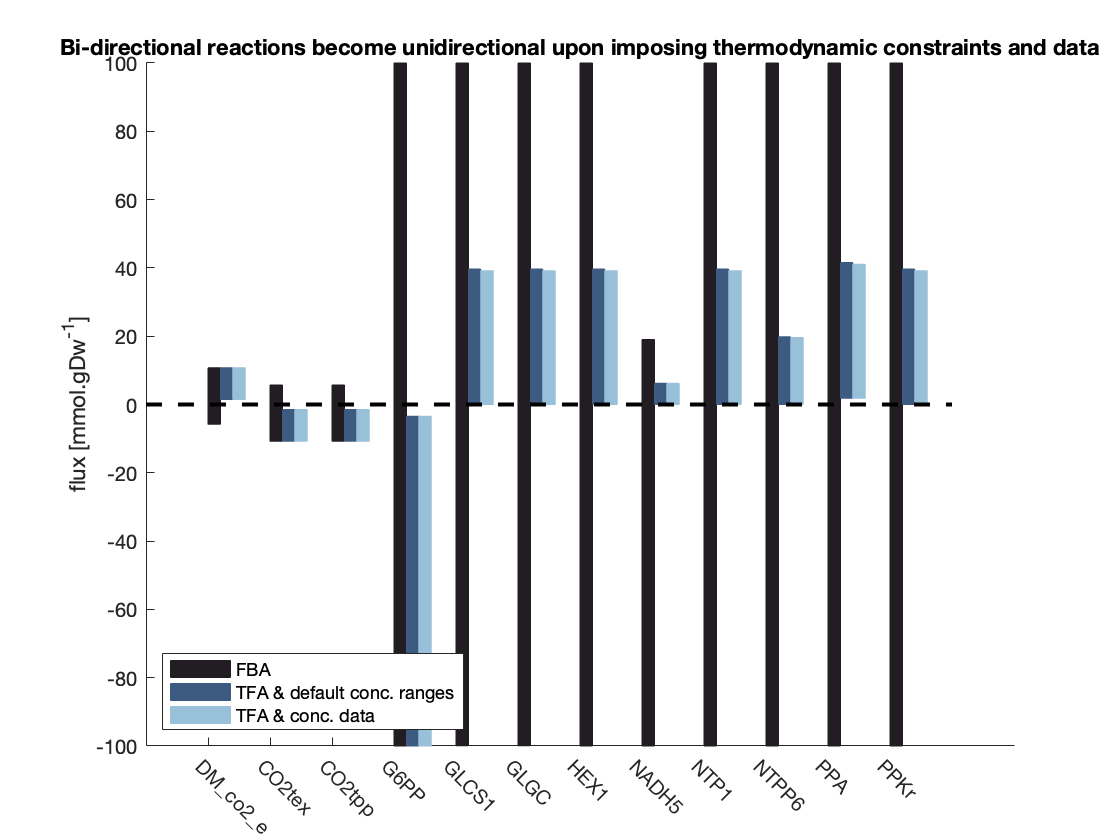

%% Plot the differences
% Inline function definitions to get:
% - values of flux ranges from a two column vector of lower and upper bounds
f = @(x) abs(x(:,2) - x(:,1));
% - logical vector with indices for bidirectional reactions (flux ranges crossing zero)
n = @(x) x(:,1)<-1e-9 & x(:,2)>1e-9;
% - scoring metric of relative changes in ranges, for ranges greater than 0.01
s = @(x,y) ( abs(f(x)-f(y))./f(x) ) .* (f(x) > 10);

% Calculate this scoring metric for the differences between
% - tfa and tva
loss = s(fva, tva);
% - tva witout and with concentration data
loss_tva_wData = s(tva, tva_wData);

% find bidirectional reactions based on
% - (1) fva
is_bd_fva = (n(fva));
% - (2) tva without concentration data
is_bd_tva = (n(tva));
% - (3) tva with concentration data
is_bd_tvawData = (n(tva_wData));

% Reactions that become unidirectional from fva (1) To tva without
% concentration data (2)
criterion1 = setdiff(find(is_bd_fva), find(is_bd_tva));
% Reactions that become unidirectional tva without (2) to tva with
% concentration data (3)
criterion2 = setdiff(find(is_bd_tva), find(is_bd_tvawData));

% We plot the ranges of these reactions
id_rxns_to_plot = [criterion1; criterion2];
xlabels = this_tmodel.rxns(id_rxns_to_plot);
figure
hold on
p1 = p_patch_va(fva(id_rxns_to_plot,:),0,[34 29 35]./255, 0.2);
p2 = p_patch_va(tva(id_rxns_to_plot,:),0.20,[61 90 128]./255, 0.2);
p3 = p_patch_va(tva_wData(id_rxns_to_plot,:),0.4,[152 193 217]./255, 0.2);
plot([0 size(id_rxns_to_plot,1)+1],[0 0],'k--','linewidth',2)
set(gca,'XTick',1:size(id_rxns_to_plot,1),'XTickLabel',xlabels,'XTickLabelRotation',-45,'TickLabelInterpreter','none')
legend([p1 p2 p3] , 'FBA', 'TFA & default conc. ranges','TFA & conc. data','Location','southwest')
ylabel ('flux [mmol.gDw^{-1}]')
title('Bi-directional reactions become unidirectional upon imposing thermodynamic constraints and data')%,'fontsize',20)

## Reactions with flux ranges affected by thermondynamic constraints

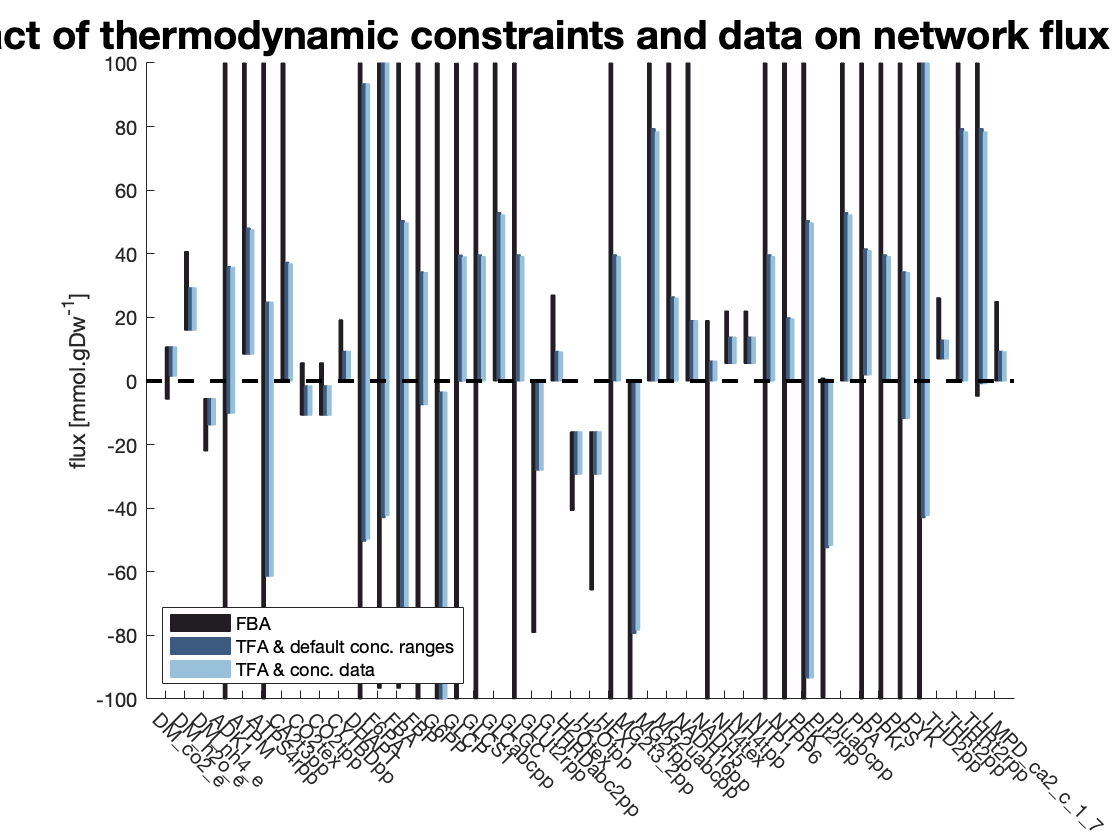

% To illustrate the impact of thermodynamics on the network we select to
% plot also the ranges of reactions that are not necessarily bidirectional
% but are affected by the addition of thermodynamics
% (1) the bi-directionals scoring higher than 0.2 (>20% difference) in the
% relative difference metric between tfa and tva
criterion3 = find(loss>0.2);
% (2) the reactions scoring higher tnan 0.2 (>20% difference) in the
% relative difference metric between tva witout and tva with concentration
% data
criterion4 = find(loss_tva_wData>0.2);

id_rxns_to_plot = union(criterion3, criterion4);
xlabels = this_tmodel.rxns(id_rxns_to_plot);
figure
hold on
p1 = p_patch_va(fva(id_rxns_to_plot,:),0,[34 29 35]./255, 0.2);
p2 = p_patch_va(tva(id_rxns_to_plot,:),0.20,[61 90 128]./255, 0.2);
p3 = p_patch_va(tva_wData(id_rxns_to_plot,:),0.4,[152 193 217]./255, 0.2);
plot([0 size(id_rxns_to_plot,1)+1],[0 0],'k--','linewidth',2)
set(gca,'XTick',1:size(id_rxns_to_plot,1),'XTickLabel',xlabels,'XTickLabelRotation',-45,'TickLabelInterpreter','none')
legend([p1 p2 p3] , 'FBA', 'TFA & default conc. ranges','TFA & conc. data','Location','southwest')
ylabel ('flux [mmol.gDw^{-1}]')
title('Impact of thermodynamic constraints and data on network flux ranges','fontsize',20)